%1
%a
E=210*10^9;
A=0.00195;
L=[4 3 5 6 5];
B=[90 180 atand(4/3) 180 180-atand(4/3)];
c=cosd([B(1) B(2) B(3) B(4) B(5)]);
s=sind([B(1) B(2) B(3) B(4) B(5)]);
k=cell(1,5);
for i=1:5
    k{i}=A*E/L(i)*[c(i)^2 c(i)*s(i) -c(i)^2 -c(i)*s(i);...
        c(i)*s(i) s(i)^2 -c(i)*s(i) -s(i)^2;...
        -c(i)^2 -c(i)*s(i) c(i)^2 c(i)*s(i);...
        -c(i)*s(i) -s(i)^2 c(i)*s(i) s(i)^2];
end

kglobal=zeros(8);

kglobal(1:2,1:2)=k{1}(1:2,1:2)+k{4}(1:2,1:2)+k{5}(1:2,1:2);
kglobal(1:2,3:4)=k{1}(1:2,3:4);
kglobal(1:2,5:6)=k{5}(1:2,3:4);
kglobal(1:2,7:8)=k{4}(1:2,3:4);

kglobal(3:4,1:2)=k{1}(3:4,1:2);
kglobal(3:4,3:4)=k{1}(3:4,3:4)+k{2}(1:2,1:2);
kglobal(3:4,5:6)=k{2}(1:2,3:4);
kglobal(3:4,7:8)=zeros(2);

kglobal(5:6,1:2)=k{5}(3:4,1:2);
kglobal(5:6,3:4)=k{2}(3:4,1:2);
kglobal(5:6,5:6)=k{2}(3:4,3:4)+k{3}(1:2,1:2)+k{5}(3:4,3:4);
kglobal(5:6,7:8)=k{3}(1:2,3:4);

kglobal(7:8,1:2)=k{4}(3:4,1:2);
kglobal(7:8,3:4)=zeros(2);
kglobal(7:8,5:6)=k{3}(3:4,1:2);
kglobal(7:8,7:8)=k{3}(3:4,3:4)+k{4}(3:4,3:4);

disp('k for member 1: ',k{1})
disp('k for member 2: ',k{2})
disp('k for member 3: ',k{3})
disp('k for member 4: ',k{4})
disp('k for member 5: ',k{5})
disp('k for global: ',kglobal)

%b
u2=0;
v2=0;
v4=0;
kreduced=kglobal;
kreduced(3:4,:)=[];
kreduced(6,:)=[];
kreduced(:,3:4)=[];
kreduced(:,6)=[];
d=kreduced\[40000;0;0;-100000;0];
d=[d(1:2);0;0;d(3:5);0];
f=kglobal*d

f = 1.0e+05 *

    0.4000
         0
   -0.4000
    0.2333
    0.0000
   -1.0000
   -0.0000
    0.7667


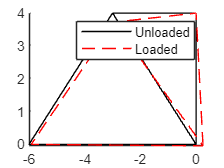

disp('Force: ', f)
disp('Displacement'. d)
d=200*d;

%c
figure
hold on
x=[0 0 -3 -6];
y=[0 4 4 0];
plot([x(1) x(2) x(3) x(4) x(1) x(3)],...
    [y(1) y(2) y(3) y(4) y(1) y(3)],"k-")

for i=1:8
    if mod(i,2)==0
        y(i/2)=y(i/2)+d(i);
    else
        n=ceil(i/2);
        x(n)=x(n)+d(i);
    end
end
plot([x(1) x(2) x(3) x(4) x(1) x(3)],...
    [y(1) y(2) y(3) y(4) y(1) y(3)],"r--")
legend("Unloaded","Loaded")
hold off